opts = bode_options_helper(1,1e4);
load PlantTF_hard.mat
load PlantTF_easy.mat;
load controller_sample.mat
C_sample = shapeit_data.C_tf;
P_hard = G;
P_easy = P;
clear G shapeit_data P;

margs = allmargin(P*C_sample);

Unrecognized function or variable 'P'.

margs.DMFrequency = margs.DMFrequency./(2*pi);
margs.GainMargin = 20*log10(margs.GainMargin);
margs
CL = feedback(P*C_samples,1)
isstable(CL)

LHS_feasible_out = [];
flag = 'pidt';
% = generate_feasible_points_LHS(100,10,P_hard, flag);
[LHS_out, LHS_info] = generate_feasible_points_LHS(flag, 100, 10, P_easy);

Test current init conditons -> NOT STABLE

Create a feasible starting point generator -> Done

review reliability of stability/unstability checker, maybe use nyqlog or something but its needs to be more reliable

change barrier function to a more smooth one

try out to map all x vector vals to logarithmic space for more smoothness

C_inputs = num2cell(LHS_out(1,:));
C_obj = PIDNotchController('pidt', C_inputs{:});
C = C_obj.C;
cost_fun_unconstrained(P_easy,C);


 Bandwidth = 65 
 Penalty = 0

CL = feedback(P_easy*C,1);
isstable(CL)

ans = logical
   1


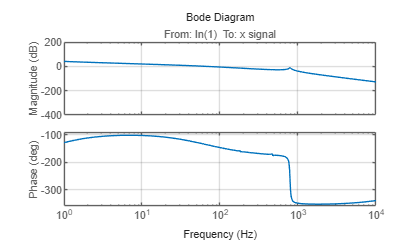

bode(P_easy*C,opts);

bode(P)